Offset and blank spot analysis.

This purpose of this script to fix the miss alignment, blank centre problem and other issues with the spot data.

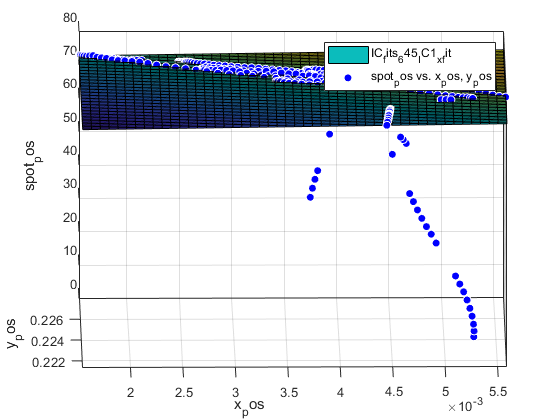

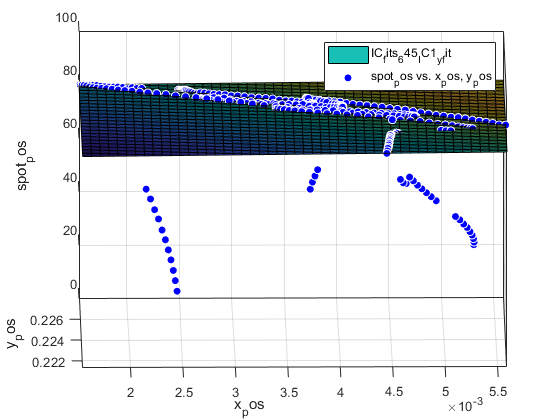

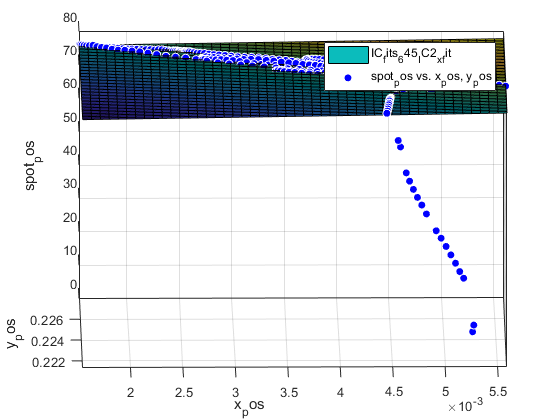

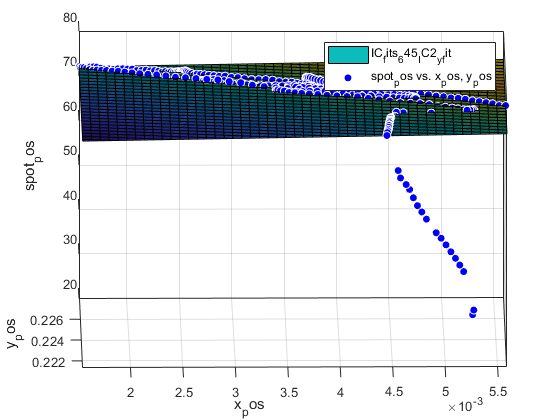

folder_name = "100W_6400us_50000fps";

folder_path = 'A:\Imperial College London\Hooper, Paul A - spots_v3';

save_path = 'A:\thermal_highspeed\Data';

load('intensity_ratio.mat');

fits=generate_image_alignment_surfaces(folder_path,folder_name);


[processed_images, t_frame, spotradius, meanmidspottemp, boundarytempgradient,IC1_full,IC2_full]=process_laser_data(folder_path,folder_name,intensity_ratio,fits);

Frame 75 shows several confusing issues the need resolving:

- The centre of the melt pool does not have a temperature

- the Hottest parts are always at the edges (>4kK)

figure;
imagesc(processed_images(:,:,75))
%ylim([50,60]);
%xlim([30,70]);
colorbar;

Cross section along Y=62

figure;
plot(processed_images(63,:,75));
xlabel('Y pixels');
ylabel('Temperature K');
title(strcat('Frame 75, ','X=55, ', folder_name));
xlim([35,75]);

Note values 53 and 54 are 293

the raw images do not display such issues


figure;
subplot(2,1,1)
imagesc(IC1_full(:,:,75))
title('Camera 1')

subplot(2,1,2)
imagesc(IC2_full(:,:,75))
title('Camera 2')

However the raw images should be aligned however they are not

filt=(fspecial('gaussian', 7,1));
thresh = 300;
odds = [1:2:1000];
intensities = [];
p1=FastPeakFind(IC1_full(:,:,75),thresh,filt,3,2);
for q = 1:2:size(p1)
    intensities = [intensities,IC1_full(round(p1(q)),round(p1(q+1)),75)];
end
true_peak = find(intensities==max(intensities));
odds = [1:2:1000];
p1=p1(odds(true_peak):odds(true_peak)+1)
x1=p1(1);
y1=p1(2);

p2=FastPeakFind(IC2_full(:,:,75),thresh,filt,3,2);
intensities = [];
for q = 1:2:size(p2)
    intensities = [intensities,IC1_full(round(p2(q)),round(p2(q+1)),75)];
end
true_peak = find(intensities==max(intensities));
p2=p2(odds(true_peak):odds(true_peak)+1)
x2=p2(1);
y2=p2(2);

Therefore the image maybe moved to a more suitable position:

IC1_full(isnan(IC1_full)) = 0;
IC1_new = imtranslate(IC1_full(:,:,75),[64-x1,64-y1],'FillValues',293, 'method', 'linear');
p1=FastPeakFind(IC1_new);
[row1,col1]=find(IC1_new == max(max(IC1_new(p1(1:2:end),p1(2:2:end)))))
figure
imagesc(IC1_new)
IC2_full(isnan(IC2_full)) = 0;
IC2_new = imtranslate(IC2_full(:,:,75),[64-x2,64-y2],'FillValues',293);

p2=FastPeakFind(IC2_new);
[row2,col2]=find(IC2_new == max(max(IC2_new(p2(1:2:end),p2(2:2:end)))))
figure
imagesc(IC2_new)

The images are now properly aligned, let us replot the temp map:

DEFAULT_FILTER_THRESHOLD = 1000;
REF_TEMPERATURE = (293:0.5:5000)';

imratio = IC1_new./IC2_new;
immultiply = IC1_new.* IC2_new;
image_temp = interp1(intensity_ratio,REF_TEMPERATURE,imratio);
image_temp(IC1_new<=300 & IC2_new<=300) = NaN;


figure;
imagesc(image_temp)
xlim([54.92 66.64])
ylim([57.69 67.61])